clear all;
close all;
clc;

This code is designed to execute the global thresholding algorithm. Created by Pablo Tejero during his internship at MaCSBio.

# HOUSEKEEPING DATA

- Gene expression data.

- Housekeeping gene lists: both Eisenberg and Housekeeping Atlas lists one.

- Housekeeping enzymes: Calculated based on the AND rules of the Genome-Scale Metabolic Model.

- Model: Genome-Scale Metaoblic Model, Human1 v1.17 is used in this project.  

currentFolder = pwd;
cd('C:/Users/PC/OneDrive/Documentos/Systems_Biology_master/Internship/Internship/Data');
data = readtable("data_TPM.xlsx");
h_k_g = readtable('NM2ENSG.xlsx');
new_hkg = readtable('ENS_ID_HKG.xlsx');
new_hkg = table2cell(new_hkg);
test_HKG = readtable('journal.pcbi.1010295.s014.xlsx', 'Sheet','Human');
test_HKG = table2cell(test_HKG);
model_p = load('model.mat');
model_p = model_p.model;
model_genes_p = model_p.genes;
cd(currentFolder)

## Data preprocessing

Expression data should be normalized to make the interpretation easier. A new matrix is created, including a first column called 'gene' including the ENSEMBL_IDs, and one column for each sample. The fene expression data is normalized based on this equation:

*normalized_data = log10(data + 1)*

The 1 is added to avoid obtaining -inf values (log10(0)) that can affect the results. Those normalized values are added to their correspondent genes and samples. The normalized table is created. 

% Colect the data needed to create the table
Ensembl_id = data(:, 1);
sampleNames = data.Properties.VariableNames(2:end); 
data_to_log = table2array(data(:, 2:end));
logged_data = log10(data_to_log + 1);%data_to_log %log10(data_to_log + 1); % Normalize the data (+1 to avoid having 0 values) 

%Create the new table with the data obtained before
log_data = [Ensembl_id, array2table(logged_data)]; % Load the data on the new table  
log_data.Properties.VariableNames(2:end) = sampleNames; % Variables names 
log_data.Properties.VariableNames{1} = 'gene'; % Change ENSEML_ID name to gene (To run findUsedGenesLevels)

## Processing the Genome-Scale Metabolic Models

Metabolic gene expression is extracted based on pruned model. 

% PRUNED MODEL
geneExpressionMatrix_P = [];

for i = 1: width(sampleNames)
    log_data.value = log_data{:, i + 1}; 
    [geneList, geneExpression] = findUsedGenesLevels(model_p, log_data); 
    geneExpressionMatrix_P = [geneExpressionMatrix_P, geneExpression'];
    log_data.value = [];
end

metabolic_genes_P = array2table(geneExpressionMatrix_P, 'RowNames', geneList, 'VariableNames', sampleNames);

% Delete the NaN values
metabolic_genes_P = rmmissing(metabolic_genes_P, 'MinNumMissing', size(metabolic_genes_P, 2)); % So we can use the local thresholding 

% Take the metabolic ENSEMBL_IDs for later
gene_names_P = metabolic_genes_P.Properties.RowNames;

# Obtain Enzymes based on StanDep code

This code is based on the code created by Joshi et al., ... For the StanDep Thresholding Algorithm.

Obtain the metabolic housekeeping genes (present in the model), and create a new matrix called data_met with the gene expression and a column called gene, with the ENSEMBL_ID.  

The original code uses log10 to normalize the data, but it was already done previously, so that part was ommited.

hkg_exp = metabolic_genes_P(ismember(metabolic_genes_P.Properties.RowNames, test_HKG), :);% h_k_g.converted_alias), :)

%Ensuring that the first colum is names 'gene' 
data_met = hkg_exp;
data_met.gene = data_met.Properties.RowNames;
columnNames = ['gene', data_met.Properties.VariableNames];
data_met = data_met(:, columnNames);
data_met.gene_1 = [];
data_met.Properties.RowNames = {};
%Although this is not documented clearly, standep will perform a log10 on
%the expression data. To ensure that this does not introduce negative
%numbers we add 1 everywhere.
%datalog10 = data_met;
%datalog10{:,2:end} = datalog10{:, 2:end};%(datalog10{:,2:end}+1)


Based on the data_met, a new specific structure (rnaData) is created, with specific fields inside, needed for later

%Standep requires a very specific pre-processing for the inputs!
%1st, the RNA data structure
rnaData = struct();
rnaData.gene = data_met.gene;
rnaData.value = table2array(data_met(:,2:end));
rnaData.valuebyTissue = table2array(data_met(:,2:end));
rnaData.Tissue = data.Properties.VariableNames(2:end)';

Obtained the expression data of those genes present in the model (metabolic). This part shouldn't be necessary, but here is not going to affect (the results should be the same)

modelData = getModelData(rnaData,model_p);

Obtain the enzymes, both specialist (those ones that appears just in one reaction) and promiscuous (those that codes more than just 1 reactions)

spec = getSpecialistEnzymes(model_p);  
prom = getPromEnzymes(model_p);

Combine both spec and prom enzymes, in a new structure, so it is possible to work with them. It is also ploted the presence of both

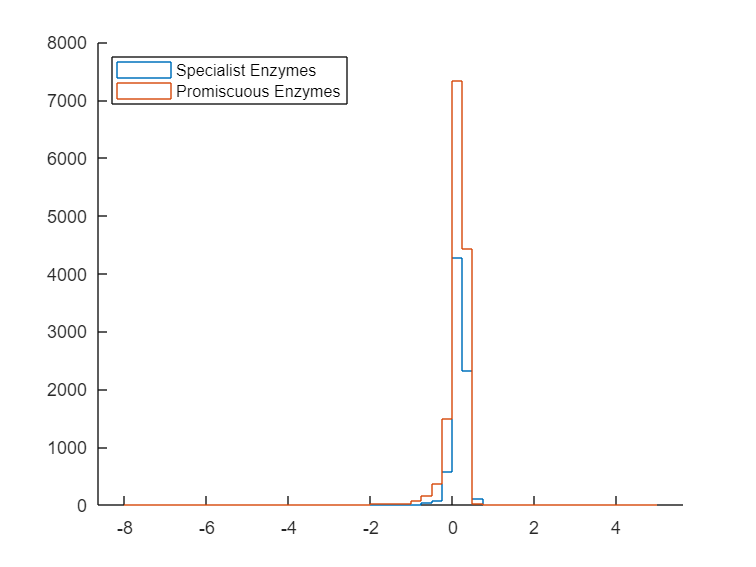

enzymeData = struct with fields:
    enzyme: {2489×1 cell}
     value: [2489×48 double]
      rxns: {2489×1 cell}
    Tissue: {48×1 cell}


enzymeData = comparePromiscuousSpecific(spec,prom,modelData)

- Step 1: Identify the rows that have all their elements equal to 0 in value

rowsToRemove = all(enzymeData.value == 0, 2);


- Step 2: Create a new structure without the corresponding rows and elements

newEnzymeData.enzyme = enzymeData.enzyme(~rowsToRemove);
newEnzymeData.value = enzymeData.value(~rowsToRemove, :);
newEnzymeData.rxns = enzymeData.rxns(~rowsToRemove);
newEnzymeData.Tissue = enzymeData.Tissue; % Tissue remains the same


- Display the new structure to verify

disp(newEnzymeData);

    enzyme: {447×1 cell}
     value: [447×48 double]
      rxns: {447×1 cell}
    Tissue: {48×1 cell}



## Extract the housekeeping reactions from the enzymes

hk_reactions = newEnzymeData.rxns;

% Extract everything and put it in a vector
% Initialize a cell array to store all elements
allElements = {};

% Traverse each cell of the original cell array
for i = 1:length(hk_reactions)
    if iscell(hk_reactions{i})
        % If the cell contains another cell array, extract its elements
        subCell = hk_reactions{i};
        for j = 1:length(subCell)
            allElements{end+1} = subCell{j}; % Add each element to the allElements cell array
        end
    else
        % If the cell does not contain another cell array, add the element directly
        allElements{end+1} = hk_reactions{i};
    end
end

% Convert the allElements cell array to a vector if necessary
% If the elements are numeric, convert the cell array to a numeric vector
if all(cellfun(@isnumeric, allElements))
    allElements = cell2mat(allElements);
end
hk_reactions_unique = unique(allElements)

hk_reactions_unique = 1×2264 cell array
  Columns 1 through 2047

    {'MAR00001'}    {'MAR00005'}    {'MAR00006'}    {'MAR00010'}    {'MAR00052'}    {'MAR00057'}    {'MAR00065'}    {'MAR00067'}    {'MAR00072'}    {'MAR00086'}    {'MAR00092'}    {'MAR00093'}    {'MAR00097'}    {'MAR00103'}    {'MAR00108'}    {'MAR00113'}    {'MAR00114'}    {'MAR00115'}    {'MAR00117'}    {'MAR00118'}    {'MAR00129'}    {'MAR00131'}    {'MAR00133'}    {'MAR00134'}    {'MAR00139'}    {'MAR00153'}    {'MAR00154'}    {'MAR00155'}    {'MAR00158'}    {'MAR00159'}    {'MAR00163'}    {'MAR00164'}    {'MAR00167'}    {'MAR00169'}    {'MAR00170'}    {'MAR00173'}    {'MAR00176'}    {'MAR00179'}    {'MAR00183'}    {'MAR00187'}    {'MAR00190'}    {'MAR00191'}    {'MAR00195'}    {'MAR00199'}    {'MAR00203'}    {'MAR00208'}    {'MAR00212'}    {'MAR00216'}    {'MAR00225'}    {'MAR00232'}    {'MAR00236'}    {'MAR00240'}    {'MAR00244'}    {'MAR00248'}    {'MAR00254'}    {'MAR00258'}    {'MAR00262'}    {'MAR00266'}    {'

## Save results

save('housekeep_react_enz_test.mat', 'hk_reactions_unique')


## Shuyis code

HK_rxns = find_housekeeping_reactions(model_p, h_k_g.converted_alias, 'strict')

HK_rxns = 1×1836 cell array
    {'MAR03905'}    {'MAR03907'}    {'MAR04097'}    {'MAR04108'}    {'MAR04133'}    {'MAR04281'}    {'MAR04388'}    {'MAR08357'}    {'MAR04360'}    {'MAR04365'}    {'MAR04368'}    {'MAR04371'}    {'MAR04381'}    {'MAR04391'}    {'MAR03989'}    {'MAR08592'}    {'MAR08589'}    {'MAR03944'}    {'MAR04130'}    {'MAR04131'}    {'MAR04132'}    {'MAR04303'}    {'MAR04414'}    {'MAR08767'}    {'MAR04383'}    {'MAR04400'}    {'MAR04401'}    {'MAR04402'}    {'MAR04706'}    {'MAR08768'}    {'MAR08341'}    {'MAR08344'}    {'MAR08727'}    {'MAR08729'}    {'MAR06537'}    {'MAR03853'}    {'MAR03857'}    {'MAR04087'}    {'MAR04091'}    {'MAR08497'}    {'MAR08500'}    {'MAR08501'}    {'MAR08502'}    {'MAR08503'}    {'MAR08504'}    {'MAR08506'}    {'MAR08507'}    {'MAR08508'}    {'MAR08509'}    {'MAR08511'}    {'MAR08516'}    {'MAR00153'}    {'MAR03212'}    {'MAR03797'}    {'MAR04331'}    {'MAR04459'}    {'MAR04460'}    {'MAR09804'}    {'MAR03163'}    {'MAR04052'}    {'MAR043